% Propelente cilíndrico com furo, da forma original vinda do Projeto Vetor I
close;
clear;
tic;

% Parâmetros constantes
alfa = 16.3;        % ângulo entre a seção divergente e eixo do motor (deg)
rho = 1730.0;       % densidade do propelente (kg/m^3)
a = 0.073;          % coeficiente de queima (m/s)
e = 1.4;            % coeficiente de erosão
n = 0.51;           % expoente de queima
R = 8.3143;         % constante universal dos gases (J/(mol * K))
g = 9.8;            % aceleração da gravidade (m/s^2)
T = 0.001;          % tamanho do passo temporal
Pa = 101325.0;      % pressão atmosférica ao nível do mar (Pa)
vsom = 340;         % velocidade do som (m/s)

% Parâmetros do motor
dg = 9.8e-3;        % diâmetro da garganta (m)
de = 19.3e-3;       % diâmetro de escape da seção divergente (m)
Ag = pi * dg^2/4;   % área da garganta (m^2)
Ae = pi * de^2/4;   % área de escape da seção divergente (m^2)
dc = 48e-3;         % diâmetro da câmara de combustão (m)
hc = 190e-3;        % comprimento da câmara de combustão (m)

% Parâmetros do propelente
din = 0.008;        % diâmetro interno do propelente (m)
dex = 0.04;         % diâmetro externo do propelente (m)
m = 0.300;          % massa inicial do propelente (kg)

% Parâmetros da estrutura
mc = 0.380*0.91+(0.0224*4)+0.1+0.1; % massa da carcaça 65mm
mm = 0.37070+0.17595;
mbb = 0.031;                        % massa do beaglebone
mpq = 0.230;                        % massa o paraquedas
me = mc + mbb + mpq + 0.2 + mm;     % massa da estrutura
mi = me + m;                        % massa inicial do foguete
A = (pi/4)*(0.085^2);               % área da seção transvesal principal do foguete
rho_Ar_0 = 0.002378 * 515.4;        % densidade inicial do ar (kg/m^3)
hmar = 1;                           % altitude inicial
Cd0 = 0.23;

% Ângulo da tubeira (rad)
AngTub = (1 + cos(alfa * pi / 180))/2;

% Volume da câmara de combustão (m^3)
Vc = (dc^2/4) * pi * hc;

% Comprimento do propelente (m)
hpr = m / (rho * pi * 0.25 * (dex^2 - din^2));

% Volume inicial do propelente (m^3)
Vp(1) = pi/4 * (dex^2 - din^2) * hpr;

% Parâmetros de partida
Pext = 101325.0;    % pressão externa inicial (Pa)
Po(1) = 20 * Pa;    % pressão interna inicial (Pa)
D(1) = dex;         % diâmetro externo inicial (m)
d(1) = din;         % diâmetro interno inicial (m)
h(1) = hpr;         % comprimento inicial (m)

v(1) = 0;
hAlt(1) = 0;

t = 0;
while(1)
    t = t + 1;

    % gamma com a pressão
    gamma(t) = 1.15032 + 0.03418 * exp(-Po(t)/(23.24512 * Pa)); %#ok<*SAGROW>

    % Pext - Calculando a pressão de saída do divergente.
    if (t == 1)
        Pext(t) = newton_raphson(Ag,Ae,gamma(t),Po(t),Pa);
    else
        Pext(t) = newton_raphson(Ag,Ae,gamma(t),Po(t),Pext(t-1));
    end

    % tau com a pressão
    tau(t) = ((2/(gamma(t) + 1))^((gamma(t) + 1)/(gamma(t) - 1)));

    % G
    G(t) = 1 - (Pext(t)/Po(t))^((gamma(t) - 1)/(gamma(t)));

    % H
    H(t) = 2 * gamma(t) * gamma(t) / (gamma(t) - 1);

    % M com a pressão
    M(t) = (26.86788 + 1.01785 * exp(-Po(t)/(40.53856 * Pa))) * 0.001;

    % To com a pressão
    To(t) = 1811 - 296.66491 * exp(-Po(t)/(27.92945 * Pa));

    % X com a pressão
    X(t) = 0.7363 + 0.11995 * exp(-Po(t)/(26.71262 * Pa));

    % rs com a pressão
    rs(t) = 0.01 * e * a * (Po(t)/Pa)^n;

    % Retrocesso e avanço dos diâmetros externo e interno durante a queima
    % Com integral
    % D(t) = dex - 2 * T * sum(rs(1:t));
    % d(t) = din + 2 * T * sum(rs(1:t));
    % Sem integral
    D(t + 1) = D(t) - 2 * T * rs(t);
    d(t + 1) = d(t) + 2 * T * rs(t);
    h(t + 1) = h(t) - 2 * T * rs(t);

    % Área de queima
    %Ab(t) = pi * hpr * (dex + din) + pi*(dex^2 - din^2)/2 ...
    %        - 6 * pi * (din + dex) * T * sum(rs(1:t));

    % Correção da Área de Queima em teste
    % Ab(t) = pi * hpr * (dex + din) + pi*(dex^2 - din^2)/2 - 4 * pi * (din + dex) * T * sum(rs(1:t));

    % Área de queima com diâmetros e comprimento atualizados
    Ab(t) = pi * h(t) * (D(t) + d(t)) + pi*(D(t)^2 - d(t)^2)/2;

    % Empuxo
    Emp(t) = AngTub * (Ag * Po(t) * sqrt(H(t) * tau(t) * G(t)) + (Pext(t) - Pa) * Ae);

    % 1a condição de parada do loop: se o avanço do diâmetro externo
    % for menor ou igual ao avanço do diâmetro interno ou se o
    % comprimento do propelente for menor que zero
    if (D(t) <= d(t) || h(t) < 0)
        break;
    end
    % 2a condição de parada do loop: empuxo menor ou igual à zero
    if(Emp(t) <= 0)
        fprintf('Empuxo Zero!!!');
        break;
    end
    % 3a condição de parada do loop: timeout da simulação, queima maior que 15 segundos
    if(t >= 15000)
        fprintf('Timeout!!!');
        break;
    end

    % Volume do propelente
    Vp(t) = pi/4 * (D(t)^2 - d(t)^2) * h(t);

    % Volume de gás na câmera
    Vo(t) = Vc - Vp(t);

    % Pressão interna
    % Po(t+1) = (Ab(t) * rs(t) * rho * X(t))/(Ag * sqrt(M(t) * tau(t) / R / To(t)));
    % Corrigido. Eq. 12.28 com o termo da esquerda zerado, pag. 599, Hill and Petterson.
    % Po(t+1) = (Ab(t) * rs(t) * rho * X(t))/(Ag * sqrt(M(t) * gamma(t) * tau(t) / R / To(t)));

    % Eq. 12.28, pag. 599, Hill and Peterson, considerando o termo de
    % variação da pressão interna e volume de gás na câmara

    % Errado
    % Po(t + 1) = Po(t) +  ((Ab(t) * rs(t) * rho * X(t)) - (Ag * sqrt(M(t) * gamma(t) * tau(t) / R / To(t)))...
    %             * Po(t)) / (Vo(t) * M(t) / (R * To(t) * T));

    % Dedução no documento - Pressão_na_câmara_de_combustão_conservação_de_massa_Nota_19_08_22
    Po(t + 1) = T * R * To(t) * Ab(t) * rs(t) * rho * X(t) / (M(t) * Vo(t))...
        + (1 - (T * Ag / Vo(t)) * sqrt(R * To(t) / M(t)) * sqrt(gamma(t) * tau(t))) * Po(t);
end

% Empuxo máximo
Emax = max(Emp)

Emax = 273.6923

% Impulso total
I = T * cumsum(Emp);

% Impulso total máximo
Imax = max(I)

Imax = 367.5811

% Impulso específico
Is = max(I)/(m*g)

Is = 125.0276

% Tempo de queima
Tq = t/1000

Tq = 1.6820

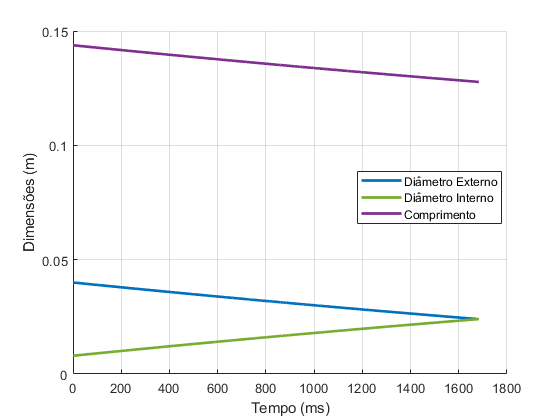

% Dimensões do propelente
figure('Name','Dimensões do Propelente');
hold on;
plot(D,'-','Color',[0 0.4470 0.7410],"LineWidth",2);
plot(d,'-','Color',[0.4660 0.6740 0.1880],"LineWidth",2);
plot(h,'-','Color',[0.4940 0.1840 0.5560],"LineWidth",2);
xlabel('Tempo (ms)');
ylabel('Dimensões (m)');
legend('Diâmetro Externo','Diâmetro Interno','Comprimento',...
    'Position',[0.638095243097771 0.467460353317715 0.258928566426039 0.126190472784497]);
grid on;
hold off;

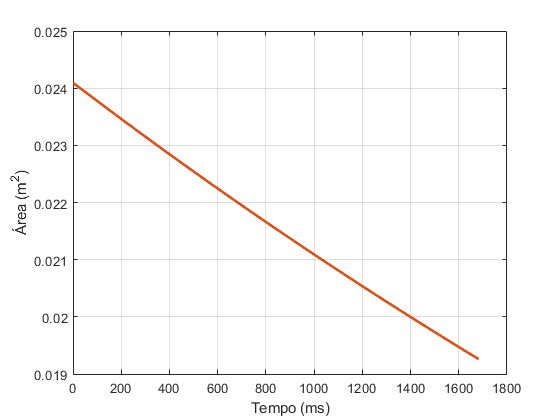

% dimFile = sprintf('sim_propelente_original/%s_dim.pdf', datestr(now,'mm-dd-yyyy_HH-MM'));
% saveas(gcf,dimFile,'pdf');
% Área de queima
figure('Name','Área de Queima');
plot(Ab,'-','Color',[0.8500 0.3250 0.0980],'LineWidth',2);
xlabel('Tempo (ms)');
ylabel('Área (m^2)');
grid on;
hold off;

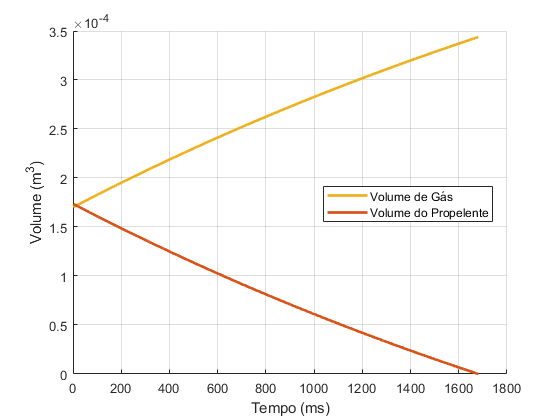

% AbFile = sprintf('sim_propelente_original/%s_AbFile.pdf', datestr(now,'mm-dd-yyyy_HH-MM'));
% saveas(gcf,AbFile,'pdf');
% Volume de gás e propelente
figure('Name','Vo e Vp');
hold on;
plot(Vo,'-','Color',[0.9290 0.6940 0.1250],'LineWidth',2);
plot(Vp,'-','Color',[0.8500 0.3250 0.0980],'LineWidth',2);
xlabel('Tempo (ms)');
ylabel('Volume (m^3)');
legend('Volume de Gás','Volume do Propelente',...
    'Position',[0.577380958713946 0.471031787091985 0.303571422238435 0.0869047596341088]);
hold off;
grid on;

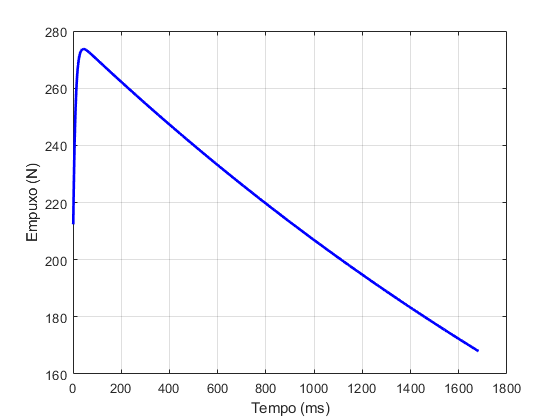

% VoVpFile = sprintf('sim_propelente_original/%s_VoVp.pdf', datestr(now,'mm-dd-yyyy_HH-MM'));
% saveas(gcf,VoVpFile,'pdf');
% Empuxo
figure('Name','Empuxo');
plot(Emp,'b-','LineWidth',2);
xlabel('Tempo (ms)');
ylabel('Empuxo (N)');
grid on;
hold off;

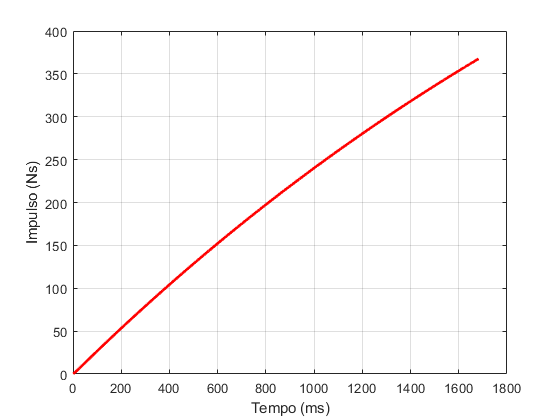

% EmpFile = sprintf('sim_propelente_original/%s_EmpFile.pdf', datestr(now,'mm-dd-yyyy_HH-MM'));
% saveas(gcf,EmpFile,'pdf');
% Impulso
figure('Name','Impulso');
plot(I,'r-','LineWidth',2);
xlabel('Tempo (ms)');
ylabel('Impulso (Ns)');
grid on;
hold off;

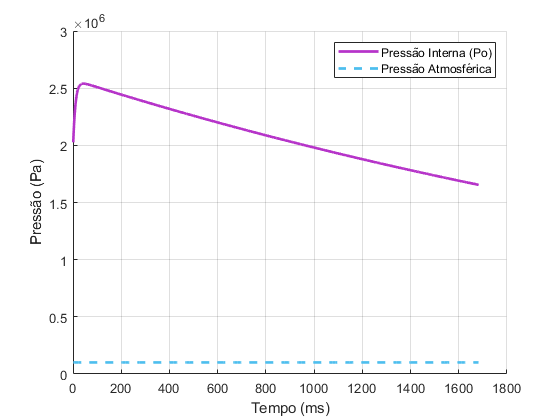

% IFile = sprintf('sim_propelente_original/%s_IFile.pdf', datestr(now,'mm-dd-yyyy_HH-MM'));
% saveas(gcf,IFile,'pdf');
% Pressão interna
figure('Name','Po');
hold on;
plot(Po,'-','Color',[0.7137 0.2039 0.7882],'LineWidth',2);
plot(Pa*ones(1,t),'--','Color',[0.3019 0.7450 0.93333],'LineWidth',2);
xlabel('Tempo (ms)');
ylabel('Pressão (Pa)');
legend('Pressão Interna (Po)','Pressão Atmosférica');
grid on;
hold off;

% PoFile = sprintf('sim_propelente_original/%s_PoFile.pdf', datestr(now,'mm-dd-yyyy_HH-MM'));
% saveas(gcf,PoFile,'pdf');
toc;

Elapsed time is 19.595369 seconds.


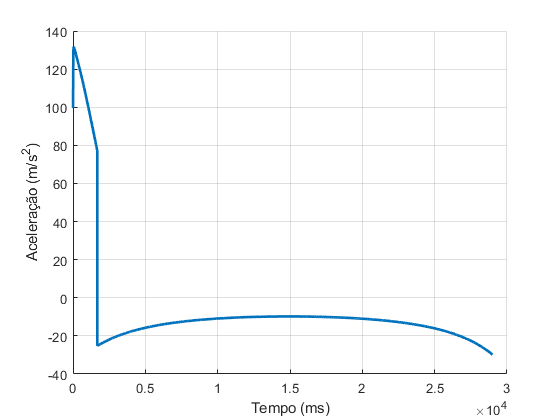

% Simulação do Voo
tVoo = 0;
while(1)
    tVoo = tVoo + 1;

    % massa do foguete
    if (tVoo <= t)
        mProp(tVoo) = h(tVoo) * (rho * pi * 0.25 * (D(tVoo)^2 - d(tVoo)^2));
        mFoguete(tVoo) = me + mProp(tVoo);
    else
        mFoguete(tVoo) = me;
    end

    P(tVoo) = mFoguete(tVoo) * g;
    rho_Ar(tVoo) = rho_Ar_0 * (1 - (0.00000688/0.3048) * (hmar+hAlt(tVoo))).^ 4.256; % densidade do ar
    % coeficiente de arrasto
    if v(tVoo) < 238
        Cd(tVoo) = Cd0;
    elseif v(tVoo) < 442
        Cd(tVoo) = 0.32308 * log(v(tVoo)/vsom) + 0.3452;
    else
        break; % modelo não funciona
    end
    %força de arrasto
    Fd(tVoo) = (1/2)*Cd(tVoo)*A*rho_Ar(tVoo)*(v(tVoo)^2);
    %força resultante
    if (tVoo <= t)
        Fr(tVoo) = Emp(tVoo) - P(tVoo) - Fd(tVoo);
    else
        Fr(tVoo) = - P(tVoo) - Fd(tVoo);
    end
    %aceleração
    Acc(tVoo) = Fr(tVoo)/mFoguete(tVoo);
    %velocidade
    v(tVoo+1) = v(tVoo) + Acc(tVoo) * T;
    %altura
    hAlt(tVoo+1) = hAlt(tVoo) + v(tVoo) * T;

    if(hAlt(tVoo + 1) < 0)
        break;
    end
end
% Aceleração
figure('Name','Aceleração');
hold on;
plot(Acc,'-','LineWidth',2);
xlabel('Tempo (ms)');
ylabel('Aceleração (m/s^2)');
grid on;
hold off;

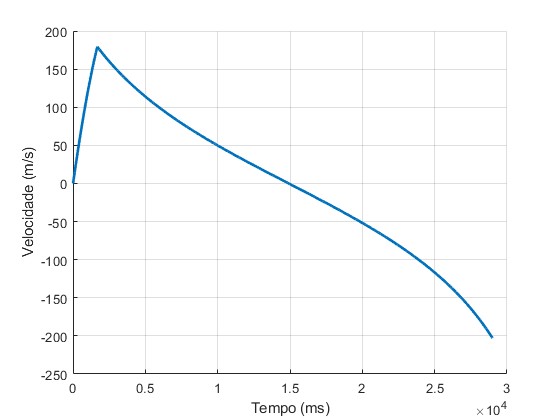

% Velocidade
figure('Name','Velocidade');
hold on;
plot(v,'-','LineWidth',2);
xlabel('Tempo (ms)');
ylabel('Velocidade (m/s)');
grid on;
hold off;

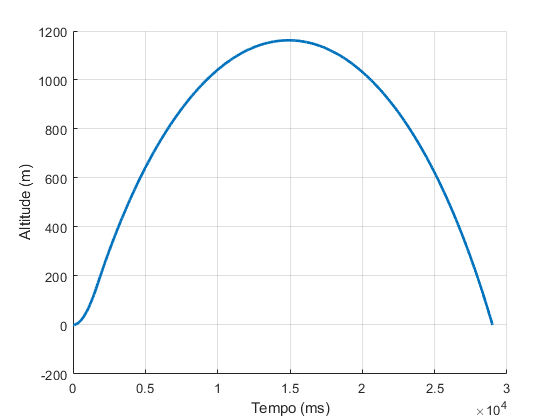

% Altitude
figure('Name','Altitude');
hold on;
plot(hAlt,'-','LineWidth',2);
xlabel('Tempo (ms)');
ylabel('Altitude (m)');
grid on;
hold off;

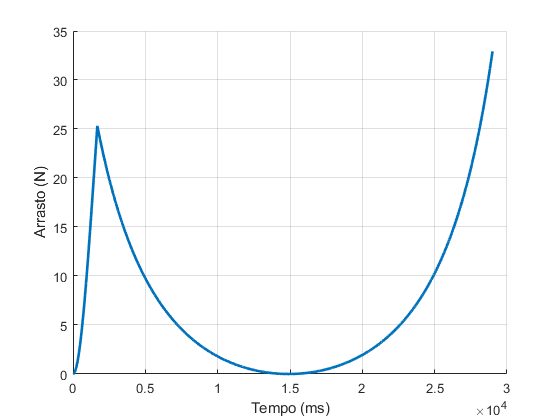

% Arrasto
figure('Name','Arrasto');
hold on;
plot(Fd,'-','LineWidth',2);
xlabel('Tempo (ms)');
ylabel('Arrasto (N)');
grid on;
hold off;

toc;

Elapsed time is 21.114394 seconds.


% Efeito Doppler
fc = 2.4e9;         % Frequência da portadora Wi-Fi 802.11b (Hz)
c = 299792458;      % Velocidade da luz (m/s)

% Frequência Doppler (transmissor se afasta do receptor inicialmente)
fd = - v * fc / c;

% Máximo shift
fdMax = max(fd)

fdMax = 1.6245e+03


% Mínimo shift
fdMin = min(fd)

fdMin = -1.4359e+03


% Frequência Observável
f = fc - fd;

% Máxima Frequência Observável
fMax = max(f)

fMax = 2.4000e+09


% Minima Frequência Observável
fMin = min(f)

fMin = 2.4000e+09

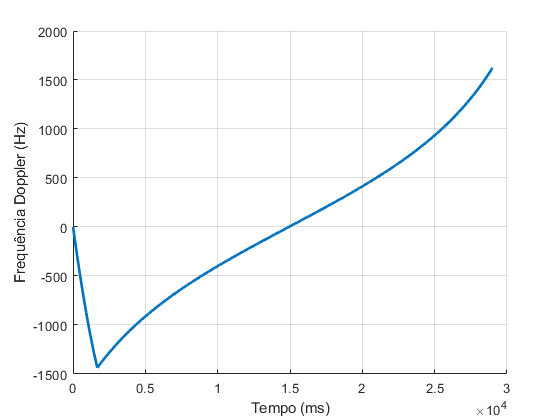


% Frequência Doppler
figure('Name','Frequência Doppler');
hold on;
plot(fd,'-','LineWidth',2);
xlabel('Tempo (ms)');
ylabel('Frequência Doppler (Hz)');
grid on;
hold off;

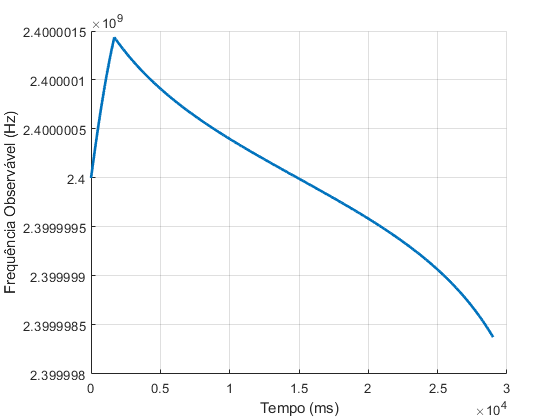

% Frequência Observável
figure('Name','Frequência Observável');
hold on;
plot(f,'-','LineWidth',2);
xlabel('Tempo (ms)');
ylabel('Frequência Observável (Hz)');
grid on;
hold off;